% Species Prediction
files = dir("history_data/*_history.csv")

files = 8×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


names = string.empty(length(files), 0);
for i = 1:length(files)
     names(i) = files(i).name;
end
names = names'

names = 8×1 string array
    "characteristic_bolete.h5_history.csv"
    "characteristic_bolete_lowres.h5_history.csv"
    "characteristic_final_bolete.h5_history.csv"
    "characteristic_final_bolete_lowres.h5_history.csv"
    "direct_bolete.h5_history.csv"
    "direct_bolete_lowres.h5_history.csv"
    "direct_final_bolete.h5_history.csv"
    "direct_final_bolete_lowres.h5_history.csv"


f = "characteristic_bolete.h5_history.csv"

t = 40×5 table
    Var1    train_loss    val_loss    train_acc    val_acc
    ____    __________    ________    _________    _______

      0      0.60109      0.58215      0.67779      0.7038
      1       0.5695      0.57615      0.70768     0.70581
      2      0.56464      0.57336      0.70884       0.705
      3      0.56138      0.57114        0.711      0.7054
      4      0.55853      0.56897      0.71289     0.70571
      5      0.55508      0.56739      0.71433     0.70711
      6      0.55338      0.56628      0.71496     0.70812
      7      0.55185      0.56515      0.71649     0.70771
      8      0.54954      0.56388      0.71798     0.70761
      9      0.54781      0.56304      0.71967     0.70761
     10      0.54607      0.56228      0.72025     0.70872
     11      0.54415      0.56166      0.72146 

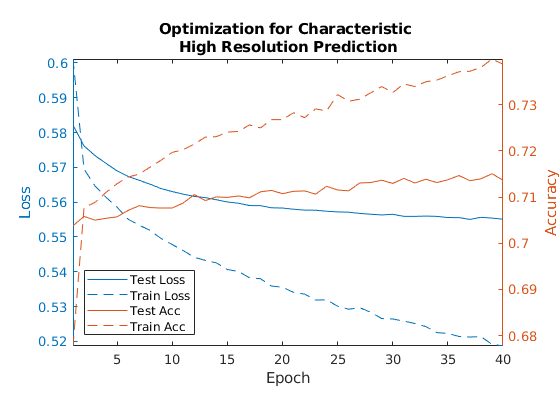

f = "characteristic_bolete_lowres.h5_history.csv"

t = 40×5 table
    Var1    train_loss    val_loss    train_acc    val_acc
    ____    __________    ________    _________    _______

      0      0.59477      0.57926      0.68138     0.70591
      1      0.56614      0.57313      0.70705     0.70571
      2      0.56032      0.57036      0.71117     0.70601
      3      0.55607       0.5683      0.71404     0.70721
      4      0.55195      0.56659      0.71673     0.70766
      5      0.54828      0.56544      0.71954     0.70837
      6      0.54486      0.56464      0.72146     0.70802
      7      0.54234      0.56336      0.72343     0.70837
      8      0.53952      0.56287       0.7254     0.70932
      9      0.53733      0.56253      0.72813     0.70867
     10      0.53492      0.56179      0.72856     0.70977
     11      0.53271      0.56151      0.73077 

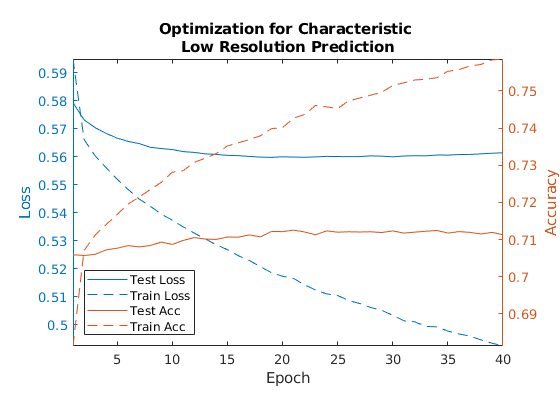

f = "characteristic_final_bolete.h5_history.csv"

t = 40×5 table
    Var1    train_acc    train_loss    val_acc    val_loss
    ____    _________    __________    _______    ________

      0      0.68459      0.59477        0.701    0.58289 
      1      0.70839      0.56764      0.70185    0.57457 
      2      0.71123      0.56286      0.70485    0.57057 
      3      0.71304      0.55949       0.7064    0.56838 
      4       0.7155      0.55663      0.70645    0.56649 
      5      0.71598      0.55435      0.70673    0.56498 
      6      0.71723      0.55216      0.70762    0.56353 
      7      0.71878      0.54973      0.70804    0.56226 
      8      0.72118      0.54783       0.7086     0.5616 
      9      0.72069      0.54611      0.70795    0.56035 
     10      0.72245      0.54425      0.70856    0.55974 
     11      0.72172       0.5437      0.70888 

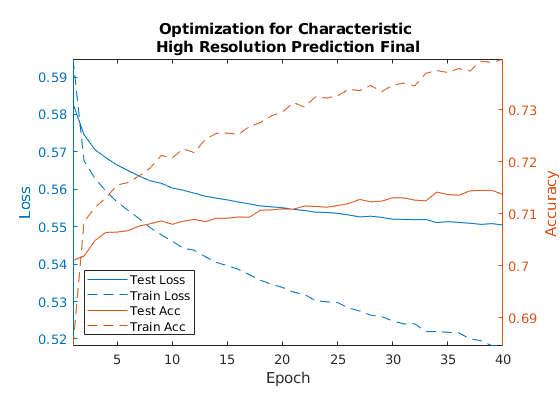

f = "characteristic_final_bolete_lowres.h5_history.csv"

t = 40×5 table
    Var1    train_acc    train_loss    val_acc    val_loss
    ____    _________    __________    _______    ________

      0       0.6825      0.59479      0.70049    0.57917 
      1      0.71024      0.56396      0.70232    0.57183 
      2      0.71494      0.55696      0.70466    0.56805 
      3      0.71818      0.55199      0.70616    0.56566 
      4      0.72186      0.54698      0.70701      0.564 
      5      0.72436      0.54353      0.70785    0.56264 
      6      0.72549      0.54027      0.70832    0.56123 
      7        0.728      0.53644      0.70949     0.5602 
      8      0.72941      0.53378      0.71132    0.55958 
      9      0.73072      0.53173      0.71039    0.55868 
     10      0.73398      0.52874      0.71156    0.55836 
     11      0.73306      0.52799      0.71207 

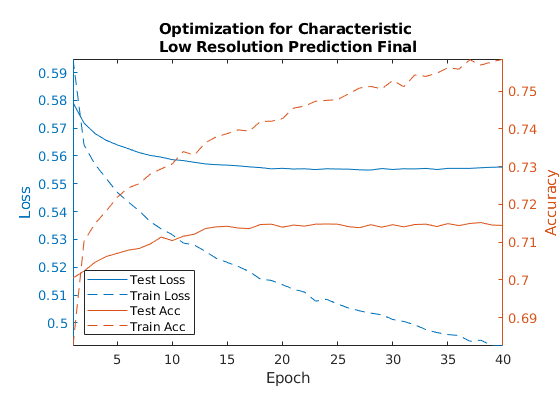

f = "direct_bolete.h5_history.csv"

t = 40×5 table
    Var1    train_loss    val_loss    train_acc    val_acc 
    ____    __________    ________    _________    ________

      0       6.0196       5.0852     0.011483     0.022901
      1       4.7341       4.8241     0.044019     0.061069
      2        4.164       4.6367      0.12057     0.083969
      3        3.653       4.4917      0.22679      0.09542
      4       3.2037       4.3504      0.32823       0.1145
      5       2.8515       4.2519      0.40096      0.12214
      6       2.4749       4.1705      0.51005      0.16794
      7       2.1633       4.0949      0.58182      0.17176
      8       1.9182       4.0648      0.64785      0.18321
      9         1.69       4.0242      0.70048      0.17557
     10       1.4858       3.9959      0.75502      0.18702
     11       1.2833       4.0021 

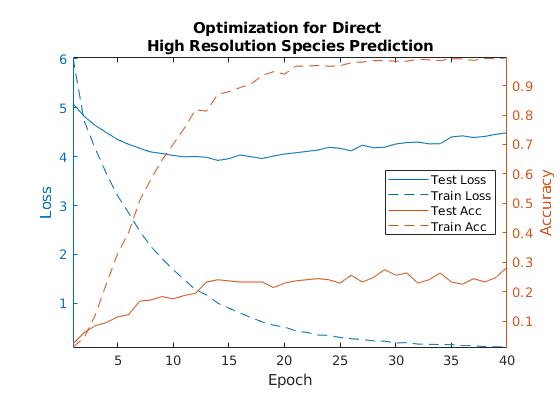

f = "direct_bolete_lowres.h5_history.csv"

t = 40×5 table
    Var1    train_loss    val_loss    train_acc    val_acc 
    ____    __________    ________    _________    ________

      0        5.8914      4.7939     0.014354     0.045802
      1        3.6875      4.5147      0.23636     0.072519
      2         2.678      4.3703      0.46411      0.13359
      3        1.9009       4.286      0.67177      0.14504
      4        1.3481      4.2426      0.80478      0.14504
      5       0.96704      4.2805      0.89187      0.14885
      6       0.69403      4.2873      0.93014       0.1374
      7       0.49625      4.3626      0.96555      0.16031
      8       0.36404      4.4105      0.98182      0.16031
      9       0.28041      4.4722      0.99139      0.16031
     10       0.21407      4.5647       0.9933      0.16031
     11       0.15651      4.5952 

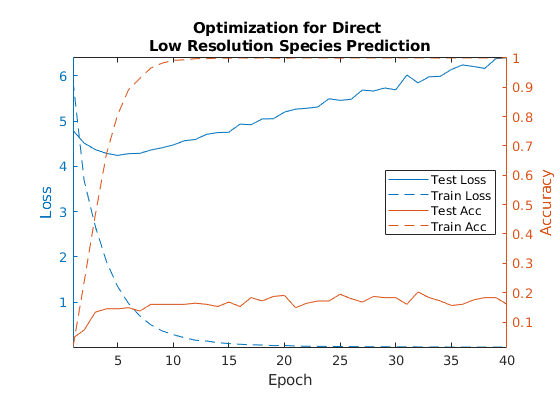

f = "direct_final_bolete.h5_history.csv"

t = 40×5 table
    Var1    train_acc    train_loss    val_acc     val_loss
    ____    _________    __________    ________    ________

      0     0.014537       5.8596      0.030303     5.1222 
      1     0.052793       4.6551      0.053476     4.8488 
      2      0.12624       4.0831      0.071301     4.6453 
      3      0.21959       3.5832      0.094474     4.5095 
      4      0.29992       3.1511       0.13012     4.3702 
      5      0.41239       2.7598       0.14617     4.2743 
      6      0.50115       2.4127       0.16221     4.1933 
      7      0.56695       2.1673       0.16934     4.1543 
      8      0.63581       1.9071       0.17469     4.1143 
      9      0.68554       1.6695       0.17825     4.1078 
     10      0.72609       1.5087       0.19073     4.0407 
     11      0.76817       1.3317 

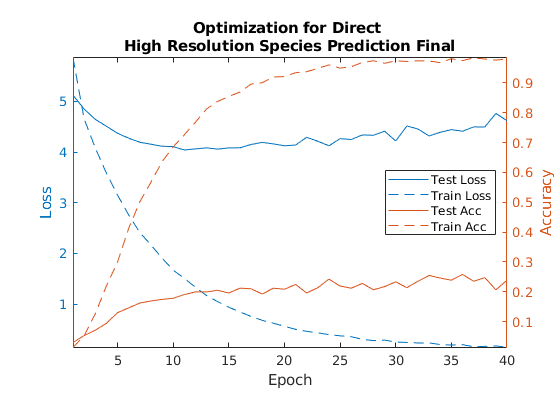

f = "direct_final_bolete_lowres.h5_history.csv"

t = 40×5 table
    Var1    train_acc    train_loss    val_acc     val_loss
    ____    _________    __________    ________    ________

      0     0.026014         5.701     0.055258     4.8381 
      1      0.21347        3.6568     0.080214     4.5512 
      2      0.42693        2.6855      0.10339     4.3865 
      3      0.62433        1.9595      0.12656     4.3065 
      4        0.772        1.4202      0.15152     4.2588 
      5      0.85998        1.0433      0.16043     4.2616 
      6      0.90207       0.77196      0.16399      4.275 
      7      0.94109       0.58824      0.16221     4.3641 
      8       0.9648       0.42921      0.15865     4.4499 
      9      0.97552       0.33449      0.17291     4.4862 
     10      0.98699       0.26982      0.17647     4.5355 
     11      0.99005       0.21169

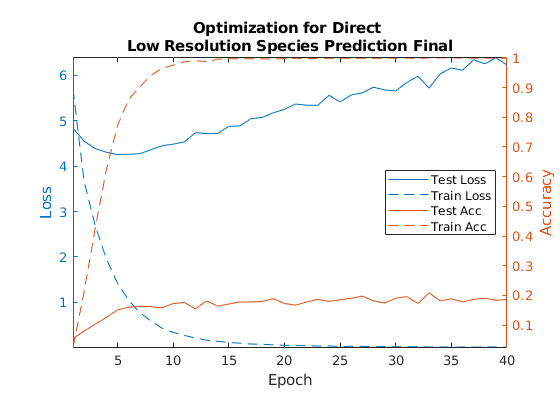


% files = dir("history_data_ed/*_history.csv")
% ed_names = string.empty(length(files), 0);
% for i = 1:length(files)
%      ed_names(i) = files(i).name;
% end
% ed_names = ed_names'
% 
% names = [names;ed_names]

for i= 1:length(names)
    f = names(i)
    t = readtable("history_data/"+f)
    fig = plotCurves(t, title_from_suffix(f));
    saveas(fig, "plots/" + replace(title_from_suffix(f), newline, "") + ".png");
end


% Edibility

files = dir("history_data_ed/*_history.csv")

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


ednames = string.empty(length(files), 0);
for i = 1:length(files)
     ednames(i) = files(i).name;
end
ednames = ednames'

ednames = 4×1 string array
    "direct_ed_bolete.h5_history.csv"
    "direct_ed_bolete_lowres.h5_history.csv"
    "direct_ed_final_bolete.h5_history.csv"
    "direct_ed_final_bolete_lowres.h5_history.csv"


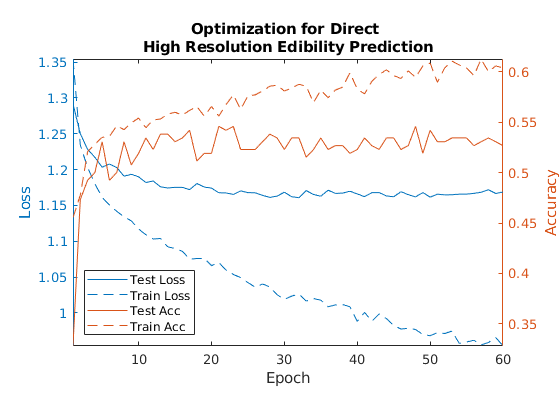

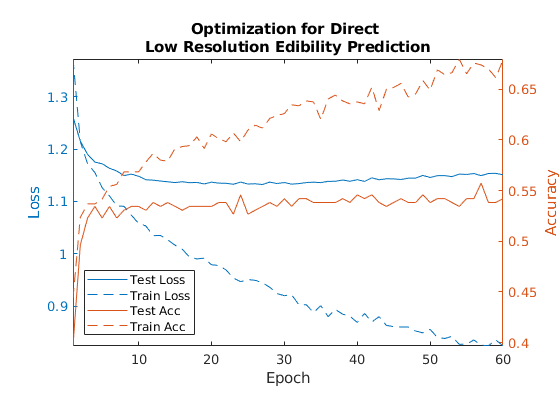

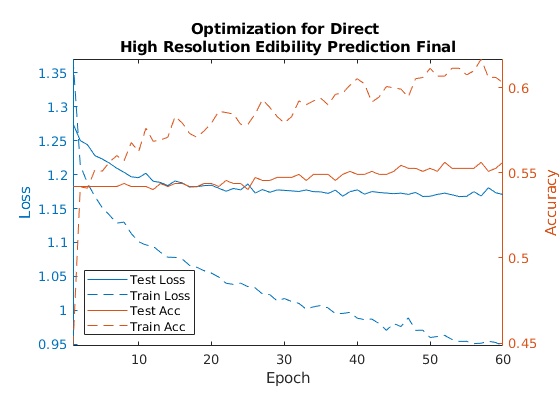

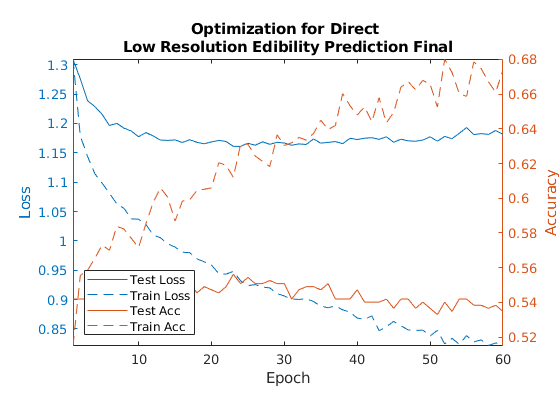

for i= 1:length(ednames)
    f = ednames(i);
    t = readtable("history_data_ed/"+f);
    fig = plotCurves(t, title_from_suffix("history_data_ed/"+f));
    saveas(fig, "plots/" + replace(title_from_suffix("history_data_ed/"+f), newline, "") + ".png");
end

function fig = plotCurves(t, name)
    fig = figure();
%     fig = figure( "Units","normalized", "Position",[0,0,0.4,0.25]);
    yyaxis left
    plotCurve(t.train_loss, t.val_loss, "Loss");
    hold on
    yyaxis right
    plotCurve(t.train_acc, t.val_acc, "Accuracy");
    hold off
    if contains(name, "direct", "IgnoreCase", true) && ~contains(name, "edibility", "IgnoreCase", true)
        loc = "east";
    else
        loc = "southwest";
    end
    
    legend(["Test Loss","Train Loss",...
        "Test Acc","Train Acc"], "Location",loc)
    title(name)
    pbaspect([1.5,1,1])
    axis tight
end
function plotCurve(train, val, type)
    plot(val)
    hold on
    plot(train)
    hold off
    ylabel(type)
    xlabel("Epoch")
end
function tit = title_from_suffix(suffix)
    tit = "Optimization for ";
    suffix = string(suffix);
    if contains(suffix, "direct")
        tit = tit + "Direct ";
    else
        tit = tit + "Characteristic ";
    end
    tit = tit + newline;
    if contains(suffix, "_bolete.h5")
        tit = tit + "High Resolution";
    else
        tit = tit + "Low Resolution";
    end
    if contains(suffix, "_ed")
        tit = tit + " Edibility Prediction";
    elseif contains(suffix, "direct")
        tit = tit + " Species Prediction";
    else
        tit = tit + " Prediction";
    end
    if contains(suffix, "_final")
        tit = tit + " Final";
    end
end